% set up time range
t = 0:0.02:10;   %vetor of time for output, 0 to 10 at 0.02 increments

%set up fixed Variables
m = 5;      %value of mass (kg)
g = 9.81    %value of gravity acceleration (m/sec^2)

g = 9.8100

omega = g / L;   %use natural cutoff frequency

%set up your transfer function
s = tf('s');    %set up transfer function input mode

%initiate Latex interpreter for legends
set(0,'defaulttextinterpreter','latex')
figure; hold on %this will put everything on one graphs
plotLegend = legend('Location','northeast'); %this puts the location of the legend for each frequency case

%do a loop for changing the length of the pedulum to see the effect on
%frequency. Remember omega=2*Pi*F
for L = 0:1:5
    sys = (1/(m*L^2))/(s^2 + omega)   %transfer function
    y = impulse(sys,t);    %step response input at t = 0
    Rad2Deg = 57.3;     %converts rads to degrees
    plot(t,Rad2Deg * y)     %plots y (remember y is in theta!)
    plotLegend.String{end} = 'omega' + string(g/L); %Writes out the Legend
end;

sys =
 
  NaN
 
Static gain.

sys =
 
     0.2
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.

sys =
 
     0.05
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.

sys =
 
   0.02222
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.

sys =
 
    0.0125
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.

sys =
 
    0.008
  ----------
  s^2 + 9.81
 
Continuous-time transfer function.



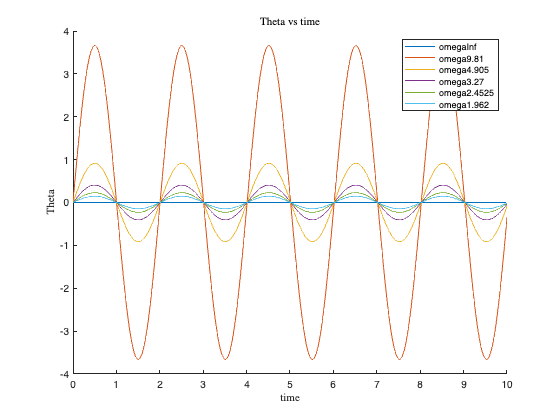


title ('Theta vs time')
xlabel ('time')
ylabel ('Theta')